# 陽的MPCコントローラの設計と実装

このサンプルでは、線形MPCの最適操作量uをテーブル参照で求めることで高速化を図る、"Explicit MPC Controller"を用いた設計の例を示す。

また、設計後のCコード生成、SIL、PILの例も合わせて紹介する。

## 初期化

clc; Simulink.sdi.clear; Simulink.sdi.clearPreferences; Simulink.sdi.close;
model_name = 'unstable_system_Explicit_MPC';
lin_controller_name = 'Linear_MPC_Controller';
exp_controller_name = 'Explicit_MPC_Controller';
ts = set_TimeStep(Simulink.data.dictionary.open('sim_data_unstable_system.sldd'));


## プラントモデルを定式化

## MPCオブジェクトを作る

線形MPCと同様であるので、説明は省略する。詳細については「Linear_MPC_Design.mlx」を参照。

plant_tf = tf(1.6, [2, 1, 0]);
plant_tf_d = c2d(plant_tf, ts);
plant_tf_d_delay = tf(plant_tf_d.Numerator, plant_tf_d.Denominator, ts, 'OutputDelay', 20);
plant_ss = ss(plant_tf_d_delay);
B = [plant_ss.B, [1; 0]];
D = [plant_ss.D, 0];
plant_ss_indist = ss(plant_ss.A, B, plant_ss.C, D, ts, 'OutputDelay', 20);
plant_ss_indist = setmpcsignals(plant_ss_indist, 'MV', 1, 'UD', 2);
mpcObj = mpc(plant_ss_indist, ts);

-->"mpc" オブジェクトの "PredictionHorizon" プロパティが空です。PredictionHorizon = 10 を試用します。
-->"mpc" オブジェクトの "PredictionHorizon" プロパティ 10 が、モデルの最大遅延 20 より小さくなっています。より大きい予測ホライズン、たとえば 30 を選択してください。
-->"mpc" オブジェクトの "PredictionHorizon" プロパティがさらに 30 に増加されました。これはモデルに遅延が含まれているためです。
-->"mpc" オブジェクトの "ControlHorizon" プロパティが空です。2 であると仮定します。
-->"mpc" オブジェクトの "Weights.ManipulatedVariables" プロパティが空です。既定の 0.00000 を仮定します。
-->"mpc" オブジェクトの "Weights.ManipulatedVariablesRate" プロパティが空です。既定の 0.10000 を仮定します。
-->"mpc" オブジェクトの "Weights.OutputVariables" プロパティが空です。既定の 1.00000 を仮定します。


mpcObj.ManipulatedVariables(1).Max = 0.2;
mpcObj.ManipulatedVariables(1).Min = -0.2;

mpcObj.PredictionHorizon = 32;
mpcObj.ControlHorizon = 1;

dist_model = ss(1, 9.120108393559096e-04, 1, 0, ts);
mpcObj.Model.Disturbance = dist_model;
noise_model = ss(0, 0, 0, 10.964781961431852, ts);
mpcObj.Model.Noise = noise_model;
mpcObj.Weights.ManipulatedVariablesRate = 0.001831563888873;
mpcObj.Weights.OutputVariables = 54.598150033144240;

## 陽的MPCを構築する

テーブル化する範囲を定義する。

range = generateExplicitRange(mpcObj);

-->遅延を状態に変換します。
   測定出力チャネル #1 に外乱が追加されていないと仮定します。



range.State.Min(:) = -10000 * ones(size(range.State.Min));
range.State.Max(:) = 10000 * ones(size(range.State.Min));
range.Reference.Min = -2 * ones(size(range.Reference.Min));
range.Reference.Max = 2 * ones(size(range.Reference.Max));
range.ManipulatedVariable.Min = mpcObj.ManipulatedVariables(1).Min - 1;
range.ManipulatedVariable.Max = mpcObj.ManipulatedVariables(1).Max + 1;

線形MPCのオブジェクトを陽的MPCに変換する。

exp_mpcobj = generateExplicitMPC(mpcObj, range)



Regions found / unexplored:        3/       0

 
Explicit MPC Controller
---------------------------------------------
Controller sample time:    0.01 (seconds)
Polyhedral regions:        3
Number of parameters:      25
Is solution simplified:    No
State Estimation:          Default Kalman gain
---------------------------------------------
Type 'exp_mpcobj.MPC' for the original implicit MPC design.
Type 'exp_mpcobj.Range' for the valid range of parameters.
Type 'exp_mpcobj.OptimizationOptions' for the options used in multi-parametric QP computation.
Type 'exp_mpcobj.PiecewiseAffineSolution' for regions and gain in each solution.


区分を最適化するために同じゲインテーブルを持つものを結合し、メモリ消費を削減することができる。

exp_mpcobj_simp = simplify(exp_mpcobj, 'exact')



Regions to analyze:        3/       3

 
Explicit MPC Controller
---------------------------------------------
Controller sample time:    0.01 (seconds)
Polyhedral regions:        3
Number of parameters:      25
Is solution simplified:    No
State Estimation:          Default Kalman gain
---------------------------------------------
Type 'exp_mpcobj_simp.MPC' for the original implicit MPC design.
Type 'exp_mpcobj_simp.Range' for the valid range of parameters.
Type 'exp_mpcobj_simp.OptimizationOptions' for the options used in multi-parametric QP computation.
Type 'exp_mpcobj_simp.PiecewiseAffineSolution' for regions and gain in each solution.


今回の例では、十分シンプルであるために最適化前と後で変化はない。

## シミュレーション

モデルを実行して動作を確認する。

open_system(model_name);

% 参照モデルをノーマルモードにセット
set_param([model_name, '/MPC_Controller'], 'SimulationMode', 'Normal');
% マニュアルスイッチをMPC側にセット
controller_sw = 2;

% set_param(model_name, 'SimulationCommand', 'update');

元々のMPCと陽的MPCの比較を行う。

set_param([model_name, '/MPC_Controller'], 'ModelName', lin_controller_name);
sim(model_name);
set_param([model_name, '/MPC_Controller'], 'ModelName', exp_controller_name);
sim(model_name);

結果を比較する。

compare_previous_run;

## コード生成

Embedded Coderコード生成結果を確認する。

return;
rtwbuild(exp_controller_name);

## SIL検証

SILモードでモデルとコードの等価性を調べる。

return;
set_param([model_name, '/MPC_Controller'], 'SimulationMode', 'Normal');
sim(model_name);
set_param([model_name, '/MPC_Controller'], 'SimulationMode', 'Software-in-the-Loop (SIL)');
sim(model_name);

結果を比較する。

compare_previous_run;

## PIL検証

「Linear_MPC_Design.mlx」と同様に、STM32 Nucleo F401REを用いたPIL検証を行う。手順については、「Linear_MPC_Design.mlx」を参照。

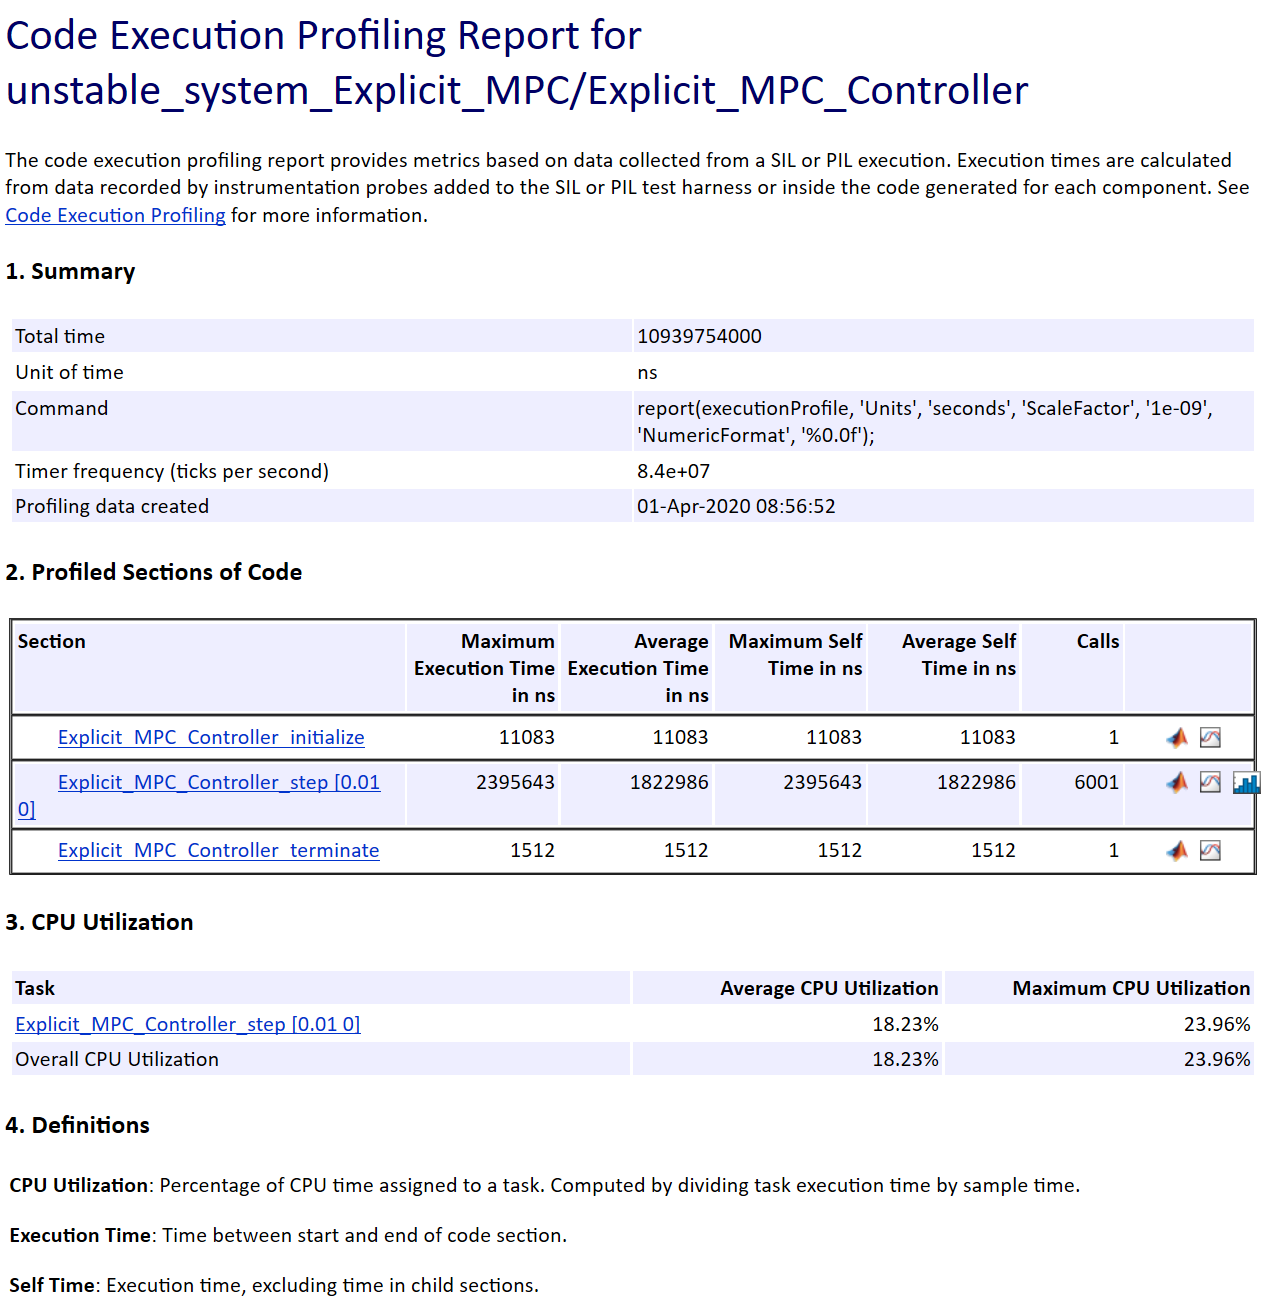

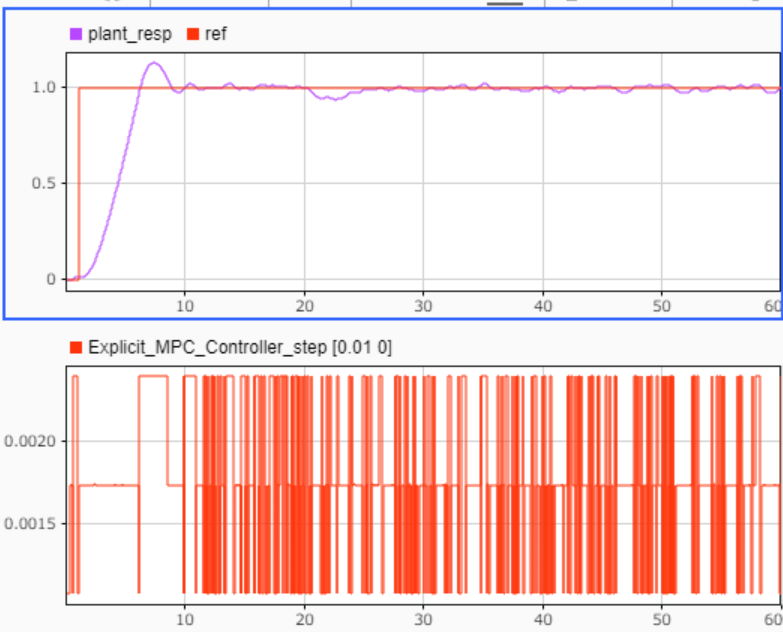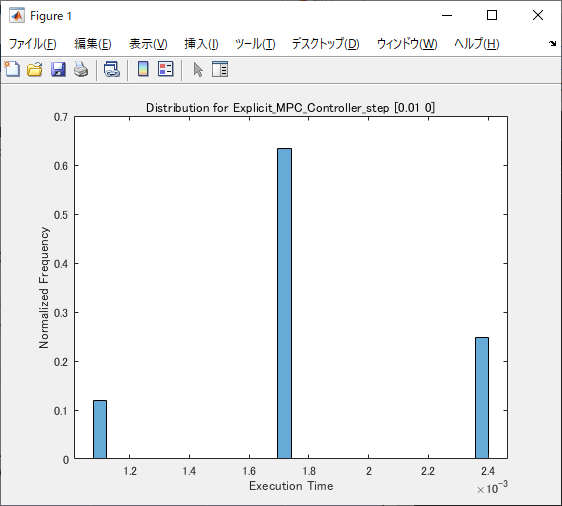

1ステップ当たりの平均計算時間は2.395ms、CPU使用率は18.23%である。

モデルとコードの実行の比較結果は以下のようになった。